clearvars
cd(fileparts(matlab.desktop.editor.getActiveFilename))
load manualSineSweep_DATA.mat;

Fs = 1800;
Ts = 1/Fs;

**Data Arrangment**

freqsInput = [100 200 300 400 500 600 700 720 740 760 780 800 820 840 860 880 900]';
wInput = freqsInput*2*pi;
relRate = slow_data.outer_enc_der;
IqMeasAX2 = fast_data.Ax2.Iq_meas(1:2:end);

%timeDimain
I_to_W_Data = iddata(relRate, IqMeasAX2, Ts, 'Domain', 'Time', 'ExperimentName', 'Sine Manual Steps', 'InputName', 'IqMeas', 'InputUnit', {'A'}, ...
    'OutputName', 'relRate', 'OutputUnit', 'deg/s', 'TimeUnit', 'seconds');

%freqDomain
I_to_W_Data_freqDomain = fft(I_to_W_Data);
I_to_W_Data_freqDomain = chgFreqUnit(I_to_W_Data_freqDomain, 'Hz');


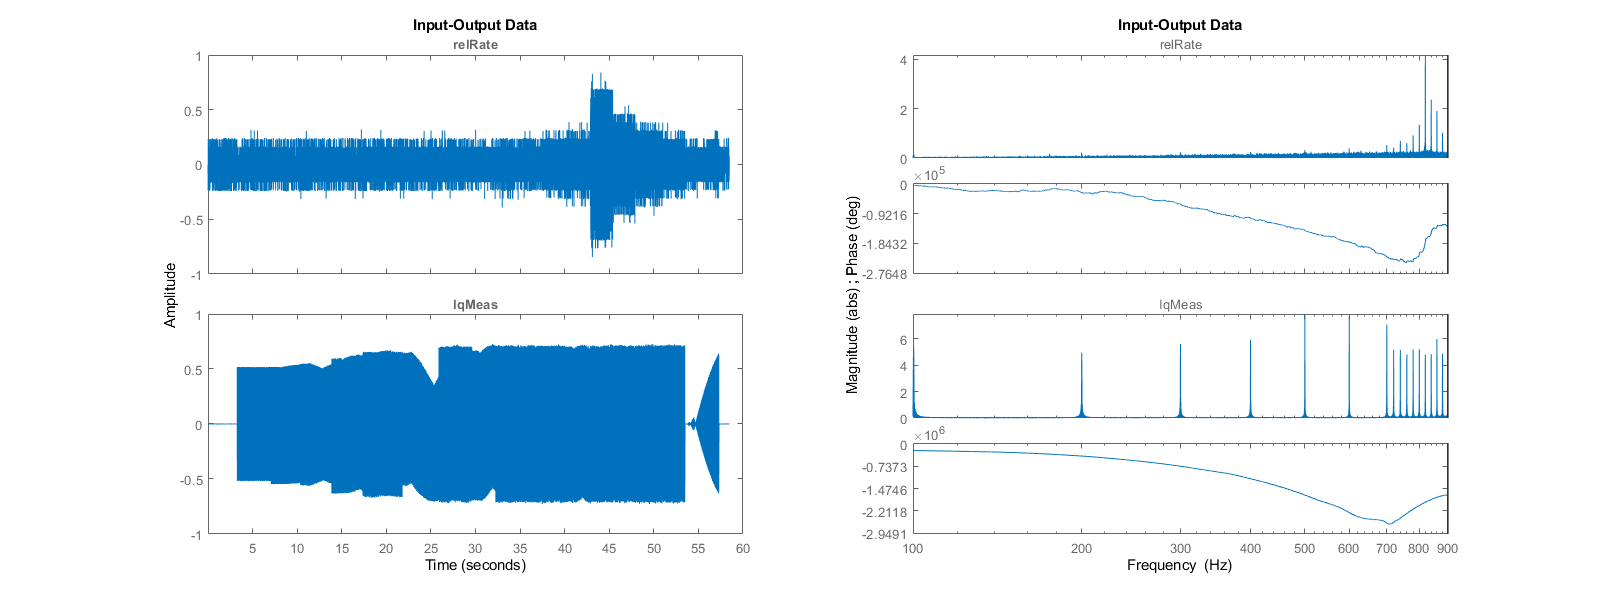

figure('Position',[0 0 1600 600])

subplot(121)
ax1 = plot(I_to_W_Data);
subplot(122)
plot(I_to_W_Data_freqDomain)
xlim([100 900])

**Estimate empirical transfer functions and periodograms - *****etfe***

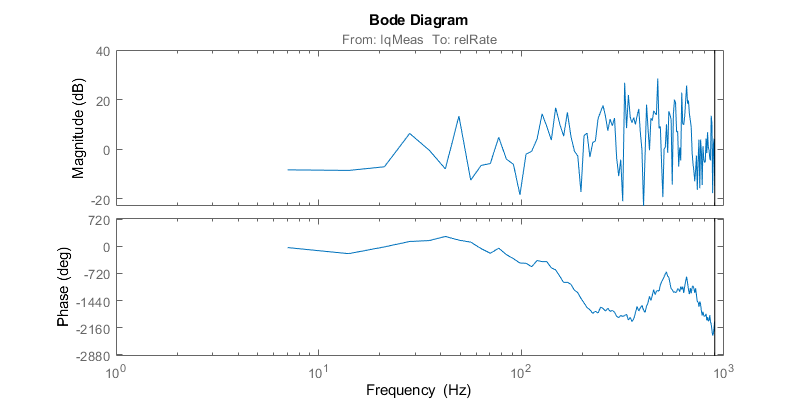

clf
TF_etfe = etfe(I_to_W_Data);
h1 = bodeplot(TF_etfe);
showConfidence(h1, 3)

**Estimate frequency response with fixed frequency resolution using spectral analysis - *****spa***

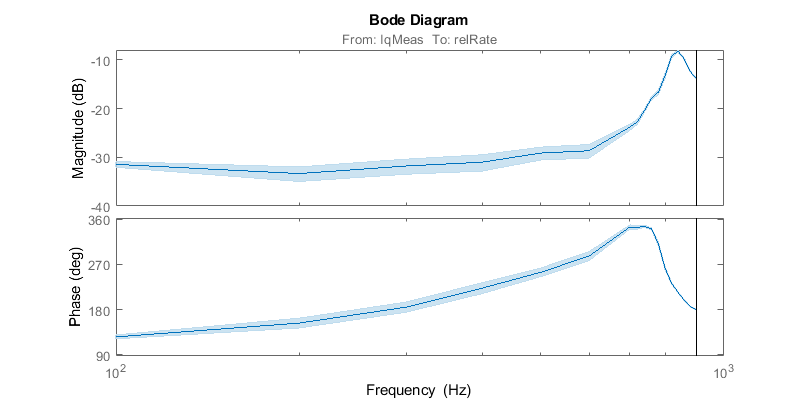

TF_iddata = spa(I_to_W_Data, [], freqsInput*2*pi);
figure('Position',[0 0 800 400])
h2 = bodeplot(TF_iddata);
showConfidence(h2, 3)

loglog(I_to_W_Data_freqDomain.Frequency*2*pi, abs(I_to_W_Data_freqDomain.OutputData./I_to_W_Data_freqDomain.InputData))

I_to_W_Data_freqDomain.FrequencyUnit

ans = 'Hz'

unique(round(I_to_W_Data_freqDomain.Frequency(abs(I_to_W_Data_freqDomain.InputData)>4),0))

ans =    100
   200
   300
   400
   500
   600
   700
   720
   740
   760


**Estimate frequency response with fixed frequency resolution using spectral analysis - *****spa***

TF_iddata = spa(I_to_W_Data, [], freqsInput*2*pi);
figure('Position',[0 0 800 400])
h = bodeplot(TF_iddata);
showConfidence(h, 3)

% systemIdentification

TF = tfest(I_to_W_Data, 3, 1,nan, 'Ts', Ts)

TF =
 
  From input "IqMeas" to output "relRate":
                          -0.02665 z^-1
  z^(-1) * -------------------------------------------
           1 + 0.8781 z^-1 - 0.8963 z^-2 - 0.9451 z^-3
 
Sample time: 0.00055556 seconds
Discrete-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                 
Estimated using TFEST on time domain data "I_to_W_Data".
Fit to estimation data: 38.97%                          
FPE: 0.006801, MSE: 0.0068                              


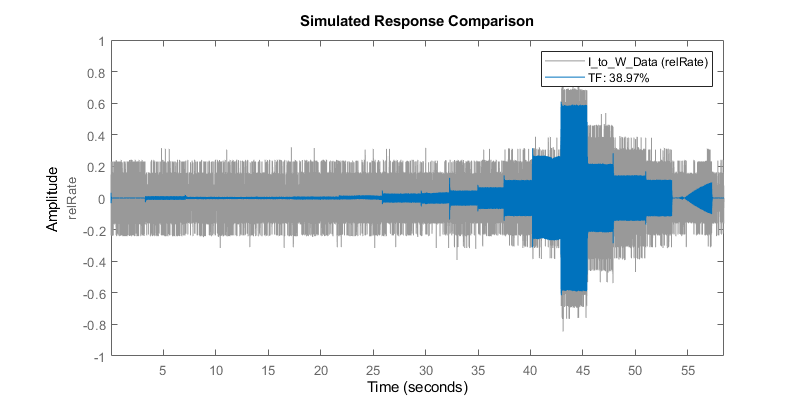

compare(TF, I_to_W_Data)

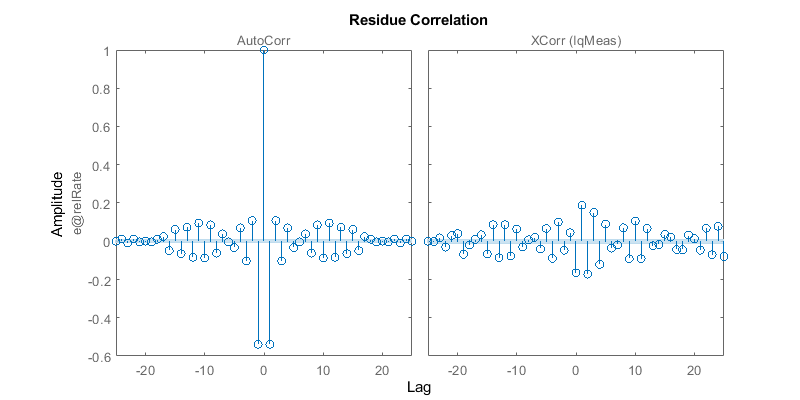

resid(TF, I_to_W_Data)